clear all
close all
f=@(x) x.^4;
I=quadratura(f,-1,2,10,1)

I = 6.4657

Ies=33/5

Ies = 6.6000

EPM=(Ies-I)/Ies

EPM = 0.0203

I=quadratura(f,-1,2,10,2)

I = 6.8692

Ies=33/5

Ies = 6.6000

ET=(Ies-I)/Ies

ET = -0.0408

I=quadratura(f,-1,2,20,3)

I = 6.6000

Ies=33/5

Ies = 6.6000

ECS=(Ies-I)/Ies

ECS = -1.9176e-06

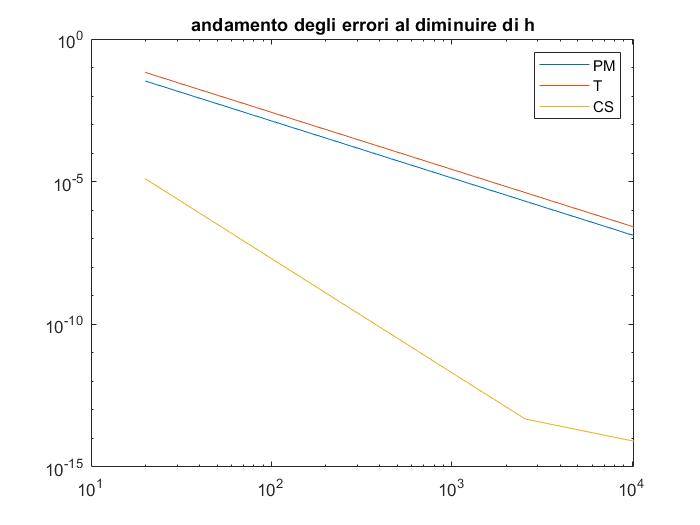

clear all
close all
f=@(x) x.^4;
Ies=33/5;
N=100;E=[];
V=[];
for n=1:10
    int=10*2^n;
    for m=1:3
        I=quadratura(f,-1,2,int,m);
        Ies=33/5;
        E(n,m)=abs((Ies-I));
    end
    V=[V int];
end
loglog(V,E(:,1))
hold on
loglog(V,E(:,2))
loglog(V,E(:,3))
legend("PM","T","CS")
title("andamento degli errori al diminuire di h")

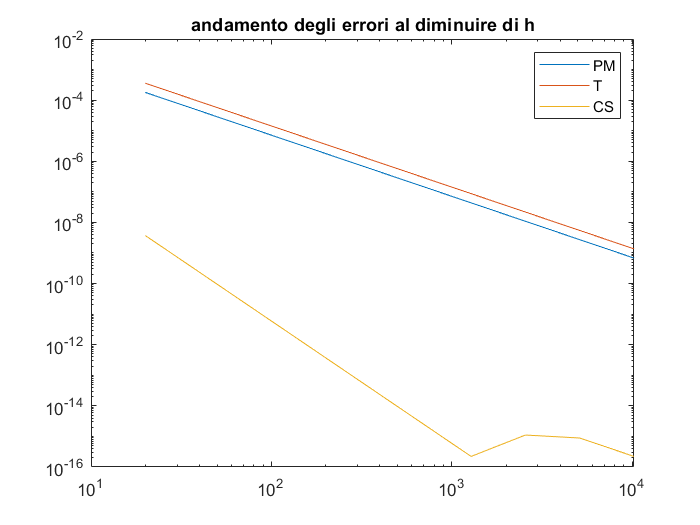

clear all
close all
f=@(x) exp(x);
a=0; b=1;
Ies=exp(b)-1;
N=100;E=[];
V=[];
for n=1:10
    int=10*2^n;
    for m=1:3
        I=quadratura(f,a,b,int,m);
        E(n,m)=abs((Ies-I));
    end
    V=[V int];
end
loglog(V,E(:,1))
hold on
loglog(V,E(:,2))
loglog(V,E(:,3))
legend("PM","T","CS")
title("andamento degli errori al diminuire di h")

clear all
close all
f=@(x) exp(x);
a=0; b=1;
Ies=exp(b)-1;
I=integral(f,a,b);
e=abs((Ies-I))

e = 4.4409e-16